# Localized Cluster Enhancement - Tutorial example - OHBM 2025

## Introduction

Localized cluster enhancement can be used as an 'add-on' analysis after a TFCE analysis. 

## Download the statbrainz package and install

First download the statbrainz package, copy it into you desired directory. Open matlab, switch to this directory and add the path to matlab.

%change to the correct directory where you installed statbrainz
cd('~/Documents/GitHub/StatBrainz/')

%add path to matlab
addSB2path

## Install the Rhyme data

The example data (Rhyme dataset, github.com/aandrella/fmridata) can be downloaded here (ohbm2025 url). First change to the correct directory and load the datasets. LCE requires the data to be in a 4D functional volume, with the 4-th dimension being each individual subject. In this case there are 13 subjects performing a Rhyme task (the dataset is subsampled for this tutorial to lower computation time of the permutation test). In addition to the data, a mask is required (MNI_mask_small), for the analysis to run optimally.

% change to the correct directory
cd('~/Desktop/statbrainz_edu_course/')

% load a 4D dataset of 13 subjects
fulldat = imgload('data/full_data_13_small.nii.gz');

% load the brain mask
MNImask = imgload('data/MNImask_small.nii.gz');

## Set-up the required parameters

In order for TFCE and LCE to work properly some parameters need to be specified beforehand. Most parameters can be left at the default values. The connectivity criterion determines when voxels are 'connected' fo form a cluster (usually left to 18 or 26). The H (=2) and E (=0.5) parameters are left to the default TFCE values, they define the height and extent of the TFCE support. The dh value should not be changed (it defines the resolution of the integral approximation). The h0 parameter is more important, it defines the lower threshold of the TFCE support. In TFCE is originally is set to 0, meaning that the support is calculated using Z > 0. As we have seen in the introduction this is not optimal for localization and may cause some false-postive regions to pop up. Better (more stable) results can be obtained when setting this value to be hight (e.g. z > 3.2). Note that this setting (just as in cluster-extent thresholding is arbitrary and needs to be set before seeing the data. For this example I have set the h0 to  Z > 4.4.

%define our parameters (standard TFCE)
connectivity_criterion = 26; H = 2; E = 0.5; dh = 0.1; h0 = 4.4;

## Peform the analysis - one-sample t-test

In this example we will use a one-sample t-test for group activation in the Rhyme contrast. First calculate the t-statistics map and mask out the non-brain voxels. 

%make the t-statistics (OLS) and mask
tstat_orig = mvtstat(fulldat);
tstat_orig = nan2zero(tstat_orig.*MNImask);

Then calculate the TFCE statistics.

%calculate the tfce_statistics values for the tstat image
tfce_tstat = tfce(tstat_orig, H, E, connectivity_criterion, dh, h0);

To do inference, we have to calculate the max(TFCE) statistic under the null-hypothesis of no activation. We do this using permutations.

%calculate the tfce_threshold using permutations
[threshold_tfce, vec_of_maxima_tfce] = perm_tfce(fulldat, MNImask, H, E, connectivity_criterion);

-------------------------------------------------------
tfce perm progress: 100.0


After calculating the threshold TFCE value (threshold_tfce) we can threshold the map to show TFCE enhanced clusters corrected for multiple comparisons.

## TFCE clusters and LCE analysis

After performing the TFCE analysis our thresholded map can be divided into separater clusters of activation. These clusters are subsequently used to perform the Local Cluster Enhancement (LCE) procedure to estimate LCE significance. First calculate the clusters that are TFCE siginficant.

% using tfce significant cluster
[number_of_tfce_clusters, ~, ~, index_locations] = numOfConComps(tfce_tstat, threshold_tfce, connectivity_criterion);
[ surviving_tfce_cluster_im, surviving_tfce_clusters, surviving_tfce_clusters_vec] = cluster_im( size(tfce_tstat), index_locations, 0.5 );

Now we can use the TFCE cluster map to calculate the LCE statistics (for each of the clusters).

% calculating the p-values using LCE
[pvals, max_tfce_within_region] = LCE(tstat_orig, surviving_tfce_clusters_vec, vec_of_maxima_tfce);

-------------------------------------------------------
Progress:  100.0


The pvals now indicate the LCE significance for each cluster.

pvals

pvals =     0.0050    0.1350    0.0040    0.0740    0.0100    0.0150    0.7350    0.0030


In principle the analysis is now done!

## Saving the LCE and TFCE cluster maps

After the analysis we can save the maps of both the TFCE and LCE analyses.

% making cluster images
% for TFCE siginficant clusters
[surviving_tfce_cluster_im, surviving_tfce_clusters, surviving_tfce_clusters_vec] = cluster_im( size(tfce_tstat), index_locations, 0.5 );

% for LCE significant clusters
lce_significant_clusters_vec = surviving_tfce_clusters_vec(find(pvals < 0.05));
lce_cluster_im = cluster_im( size(tfce_tstat), lce_significant_clusters_vec, 0.5 );

%write to file
hdr = spm_vol('data/MNImask_small.nii'); % just for use as a template
hdr.fname = 'lce_cluster_im.nii';
spm_write_vol(hdr, lce_cluster_im);

hdr.fname = 'tfce_cluster_im.nii' % use the same template, but change the name

hdr = struct with fields:
      fname: 'tfce_cluster_im.nii'
        dim: [46 55 46]
         dt: [16 0]
      pinfo: [3×1 double]
        mat: [4×4 double]
          n: [1 1]
    descrip: '2501.4 2025-04-22T09:56:22+01:00'
    private: [1×1 nifti]


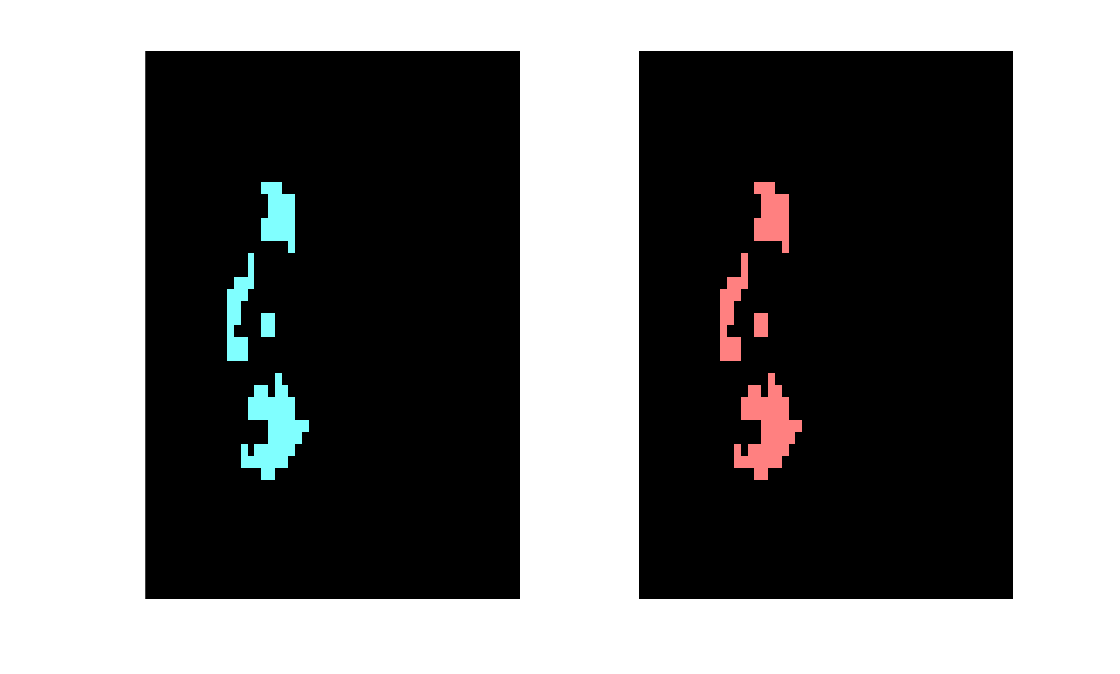

spm_write_vol(hdr, surviving_tfce_cluster_im);

% and view the results
subplot(1,2,1); viewthresh(squeeze(surviving_tfce_cluster_im(:,:,12)), [0.5,1,1]); title('TFCE', 'color', 'white');
subplot(1,2,2); viewthresh(squeeze(lce_cluster_im(:,:,12)), [1,0.5,0.5]); title('LCE', 'color', 'white');